# Time evolution for a DAE system on a star graph

Evolves the basic heat equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you must choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

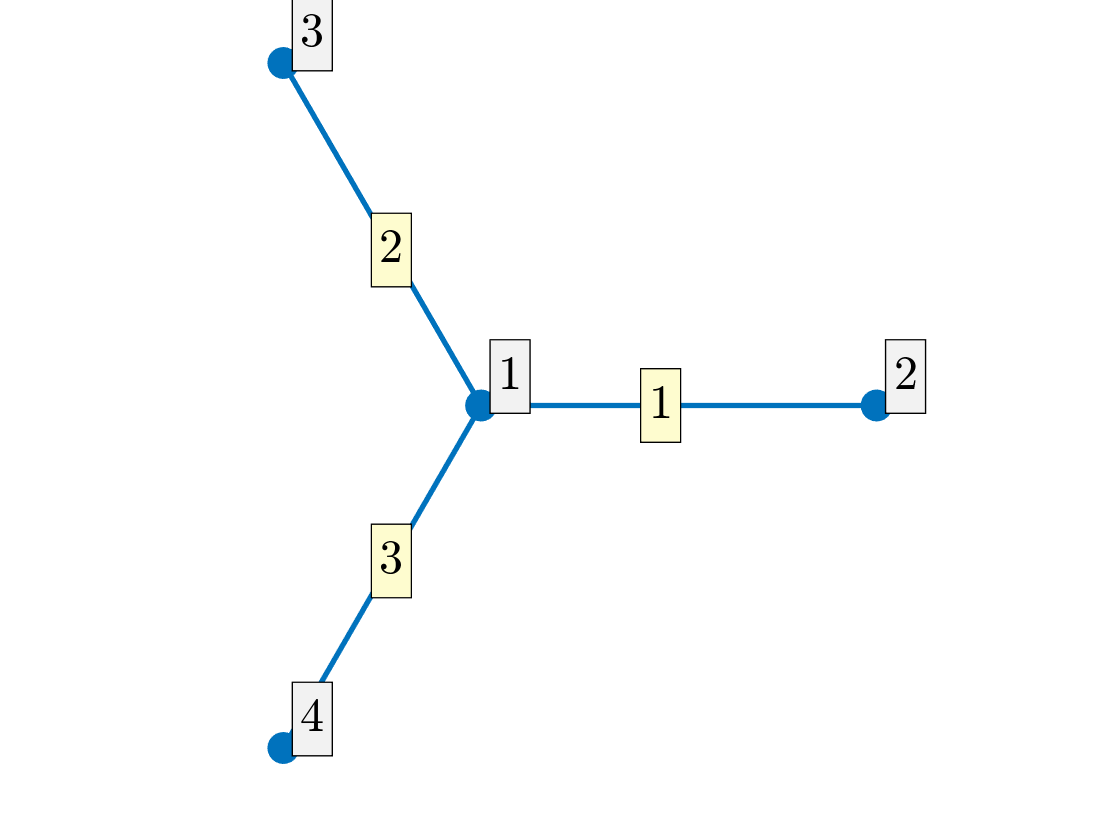

Phi = quantumGraphFromTemplate('star','discretization','Chebyshev','nX',16);
Phi.plot('layout')

## Define the function

1 = Heat

2 = Schrodinger

3 = KPP

4 = NLS

type = 2;
f = Phi.myFunc(type);

## Time evolution

You need an initial condition, step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I put a soliton on one of the edges of the star graph and propogated it towards the junction.

xgrid = pi*chebptsSecondKind(16)';
u0 = [zeros(1,18) -exp(1i*xgrid)+1 zeros(1,18)]';
tend = 5;
[u,t] = Phi.timeEvolveDAE(f,u0,1e-05,tend,8);

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every 100th data point.

scale = 5000;
fignum = 1;
for i=1:5001 %size(u,2)/scale
    if type == 1
        Phi.plot(u(:,scale*i))
        title(['$t=$',num2str( t(scale*i) )])
        axis([-5 5 -5 5 -5 5])
        daspect([1 1 1])
        zlabel('$u$')
        pause(.000000001)
    else
        figure(fignum)
        Phi.plot(abs(u(:,scale*i)).^2)
        title(['$t=$',num2str( t(scale*i) )])
        axis([-3 3 -3 3 -1 5])
        daspect([1 1 1])
        zlabel('$u^2$')
        pause(.000000001)
        
        filename = 'starTimeEvol.gif';
        del = 0.01; % time between animation frames
        drawnow 
        frame = getframe(fignum);
        im = frame2im(frame);
        [imind,cm] = rgb2ind(im,256);
        if i == 1
            imwrite(imind,cm,filename,'gif','Loopcount',inf,'DelayTime',del);
        else
            imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',del);
        end
        fignum = fignum + 1;
        close all
    end
end

## Saving Visual Data

Setting the path

Generating lots of PNG's

for i=1:5%size(u,2)/scale
    Phi.plot(abs(u(:,scale*i)).^2)
    title(['$t=$',num2str( t(scale*i) )])
    axis([-3 3 -3 3 -1 5])
    daspect([1 1 1])
    zlabel('$u^2$')
    pause(.000000001)
    
    filename = ['Fig_',num2str(i),'.png'];
    ax=gca;
    exportgraphics(ax,sprintf('FIG_%d.png',i));
    close all
end

Generating a GIF

for fignum=1:size(u,2)/scale
    figure(fignum)
    Phi.plot(abs(u(:,scale*i)).^2)
    title(['$t=$',num2str( t(scale*i) )])
    axis([-3 3 -3 3 -1 5])
    daspect([1 1 1])
    zlabel('$u^2$')
    pause(.000000001)
    
    filename = 'starTimeEvol.gif';
    del = 0.01; % time between animation frames
    drawnow 
    frame = getframe(fignum);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    if i == 1
        imwrite(imind,cm,filename,'gif','Loopcount',inf,'DelayTime',del);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append','DelayTime',del);
    end
    fignum = fignum + 1;
    close all
end

## Saving and loading the data

Save data

save('star_nx16_h10neg5.mat','u');

Load data

savedmat=matfile('star_nx16_h10neg5').u;

## Error Analysis

We use an analytical solution to 

% if type == 1
%     uana = @(t) exp(-lambda*t).*u0;
% else
%     uana = @(t) exp(-1i*lambda*t).*u0;
% end
% error = zeros(1,size(u,2));
% 
% for i=1:size(u,2)/scale
%     error(scale*i) = max(uana(t(scale*i)) - u(:,scale*i));
% end
% 
% disp('The error is:')
% disp(abs(max(error)))
